clear
filename = "files/switchingAFCMulti.mat";
% filename = "files/switchingAFC.mat";


figure
load(filename)
y = data.y(1:5000);
% plot(y)

Fs = 5000;

[f, p] = FreqAnalysis(Fs, y);

p(1:3) = 0;
plot(f, p, "LineWidth",1.5)
ylim([-2, 2])

sum(p)

ans = 13.4362

sum(p(p>0.02))

ans = 1.9391

power_density = sum(p(p>0.01))/sum(p)

power_density = 0.2436

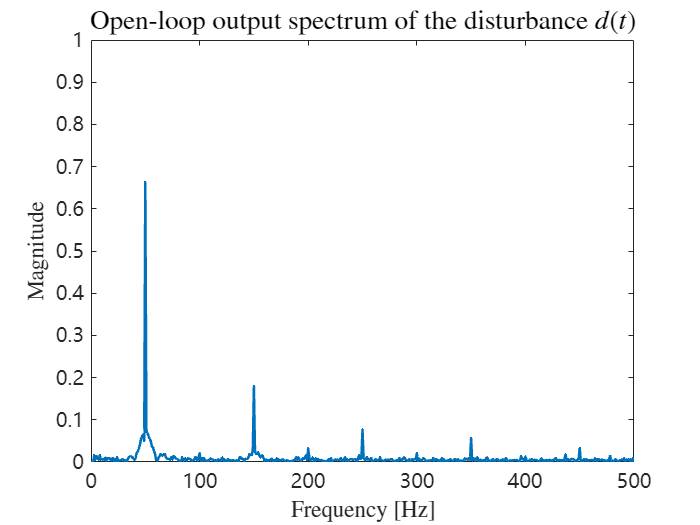

set(gca,'FontName','Times New Rome','FontSize',12);
title("Open-loop output spectrum of the disturbance $d(t)$", "Interpreter","latex","FontSize",16);
xlabel('Frequency [Hz]', "FontSize",14, "Interpreter","latex")
ylabel('Magnitude', "FontSize",14, "Interpreter","latex")
xlim([0, 500])

ylim([0, 1])

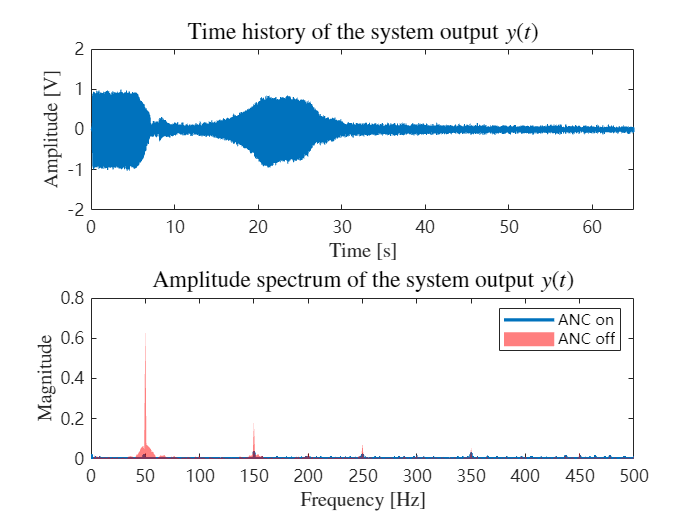

% clear
figure
load("files/bandpass.mat")
load(filename)
y = data.y(1:end);
t = (1:length(y))/5000;
% plot(y)
% ylim([-2, 2])

res = filter(bandpass50,y) + filter(bandpass150,y) + filter(bandpass100,y);
% res = filter(bandpass50,y);
subplot(2,1,1);
plot(t, res)
set(gca,'FontName','Times New Rome','FontSize',10);
title("Time history of the system output $y(t)$", "Interpreter","latex","FontSize",14);
xlabel('Time [s]', "FontSize",12, "Interpreter","latex")
ylabel('Amplitude [V]', "FontSize",12, "Interpreter","latex")
Fs = 5000;
ylim([-2, 2])
xlim([0,65])
% set(gca,'XTick',(0:10:65))
% set(gca,'YTick',(-1.5:0.5:1.5))

y = data.y(200000:end);

[fy, py] = FreqAnalysis(Fs, y);
py(1:3) = 0;
subplot(2,1,2);
% hold on
pd = plot(fy, py, "LineWidth",2);
pa = patch(f, p, 'red', ...
          'FaceAlpha', 0.5, ...
          'EdgeColor', 'None');
set(gca,'FontName','Times New Rome','FontSize',10);
title("Amplitude spectrum of the system output $y(t)$", "Interpreter","latex","FontSize",14);
ylim([-2, 2])
xlabel('Frequency [Hz]', "FontSize",12, "Interpreter","latex")
ylabel('Magnitude', "FontSize",12, "Interpreter","latex")
xlim([0, 500])
ylim([0, 0.8])
set(gca,'XTick',(0:50:500))
set(gca,'YTick',(0:0.2:1))
legend(["ANC on", "ANC off"])

% hold on
% hold off


% u = data.u(1:end);
% plot(u)
% Fs = 5000;
% 
% [f, p] = fftFunc(Fs, length(u), u);
% 
% plot(f, p)
% title("单边振幅频谱")
% xlabel('frequency')
% ylabel('|Y(f)|')
% xlim([0, 1000])
% ylim([0, 1])

% y=data.y;
rawdata = res;
[cfs,frq] = cwt(rawdata,Fs, FrequencyLimits=[10 500]);
tms = (0:numel(rawdata)-1)/Fs;
figure

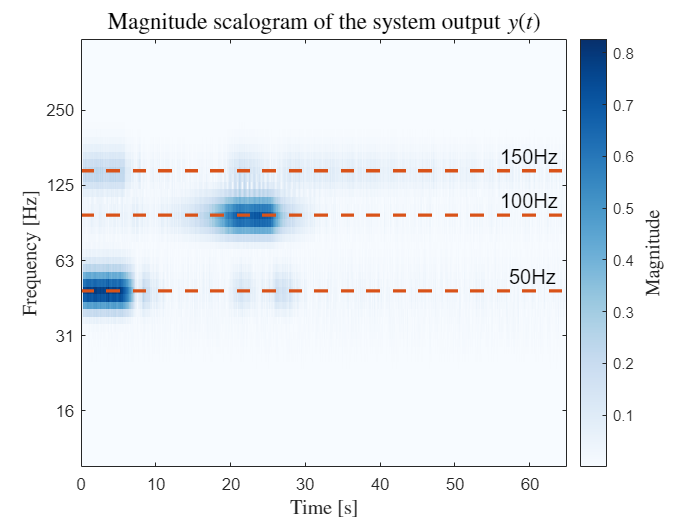

imagesc(abs(cfs))
axis tight
shading flat
xlabel("Time [s]","FontSize",12, "Interpreter","latex")
ylabel("Frequency [Hz]","FontSize",12, "Interpreter","latex")
xticks(0:50000:300000)
xticklabels((0:50000:300000)/5000)
yseg = 0:10:57;
yticks(yseg)
yticklabels(round(frq(yseg+1)))
c = colorbar;
c.Label.String = 'Magnitude';
c.Label.FontSize = 12;
c.Label.Interpreter = 'latex';
% % pcolor(t, wf, abs(wt));
% [minf,maxf] = cwtfreqbounds(numel(res),Fs)
% numfreq = 4;
% freq = logspace(log10(10),log10(500),numfreq);
% AX = gca;
% AX.YTickLabelMode = "auto";
% AX.YTick = round(freq);
title("Magnitude scalogram of the system output $y(t)$", "Interpreter","latex","FontSize",14);
% ylim([10, 500])
% % xlim([0,65])
colormap(othercolor("Blues9"))
hold on
plot([0,numel(rawdata)-1],[getYimg(50), getYimg(50)],'--',LineWidth=2,Color="#D95319")
text(57.25*5000,getYimg(50)-2,'50Hz','FontSize',12)
plot([0,numel(rawdata)-1],[getYimg(100), getYimg(100)],'--',LineWidth=2,Color="#D95319")
text(56*5000,getYimg(100)-2,'100Hz','FontSize',12)
plot([0,numel(rawdata)-1],[getYimg(150), getYimg(150)],'--',LineWidth=2,Color="#D95319")
text(56*5000,getYimg(150)-2,'150Hz','FontSize',12)
hold off

% % y=data.y;
% [cfs,frq] = cwt(res,Fs, FrequencyLimits=[10 500]);
% tms = (0:numel(res)-1)/Fs;
% figure
% surf(tms,frq,abs(cfs))
% view(2)
% axis tight
% shading flat
% xlabel("Time (s)")
% ylabel("Frequency (Hz)")
% set(gca,"yscale","log");
% c = colorbar;
% c.Label.String = 'Magnitude';
% % pcolor(t, wf, abs(wt));
% [minf,maxf] = cwtfreqbounds(numel(res),Fs)
% numfreq = 5;
% freq = logspace(log10(10),log10(500),numfreq);
% AX = gca;
% AX.YTickLabelMode = "auto";
% AX.YTick = round(freq);
% title("Magnitude scalogram of the system output $y(t)$", "Interpreter","latex","FontSize",14);
% ylim([10, 500])
% % xlim([0,65])
% colormap(othercolor("Blues9"))
% hold on
% plot([0,65],[50, 50],'--',LineWidth=2,Color="#D95319")
% plot([0,65],[100, 100],'--')
% plot([0,65],[150, 150],'--')
% hold off

% load("files/switchingAFCMulti.mat")
% y = data.y(1:end);
% load("files/switchingAFCMulti_algo.mat")
% eta_p = data.eta(1:end);
% p = data.sigma(1:end);
% 
% puy=figure;
% subplot(3,1,1);
% plot(y,"LineWidth",1.5)
% xlabel("t(s)")
% ylabel("model output y")
% title("")
% %ylim([-3,8])
% subplot(3,1,2);
% plot(p,"LineWidth",1.5);
% xlabel("t(s)")
% ylabel("controller index \sigma")
% title("")
% ylim([0,20])
% subplot(3,1,3);
% plot(eta_p,"LineWidth",1.5);
% title("")
% ylim([-1.5,2.5])
% xlabel("t(s)");
% ylabel("$\eta$",'Interpreter','Latex');
% %saveas(puy,"basicExample_uy.eps");
% 
% 
% load("exp3HHC.mat");
% y=out.get(1).Values;
% puy=figure;
% plot(y)
% xlabel("t(s)")
% ylabel("model output y")
% title("")
% ylim([-6,3])

function [f, p] = fftFunc(Fs, y)
L=length(y);
NFFT = 2^nextpow2(L);
Y = fft(y,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2);
p = 2*abs(Y(1:NFFT/2));
end

function y_img = getYimg(y)
L = log10(500)-log10(10);
l = 57;
y_img = 57 - (log10(y)-log10(10))/L*l + 0.5;
end

function [f, P1] = FreqAnalysis(Fs, y)

Y = fft(y);
L = length(y);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

end